%% baseline_sweep.m
% Sweeps homogeneous internode length from 10 to 160 um
% Measures conduction velocity for each length
% All other parameters clamped (strict isolation)
% CV calculated using velocities() - same method as Carcamo2017Cortex.m

clear; clc;

% Sweep range
L_values_um = 10:5:160;
CV = zeros(1, length(L_values_um));

for k = 1:length(L_values_um)

    % Reload fresh parameters every iteration to avoid parameter drift
    load('Carcamo2017CortexAxon.mat');
    par = axon;

    % Only biological parameter we vary - strict isolation
    % axon diameter, g-ratio, numlamellae, node dimensions all fixed
    par = UpdateInternodeLength(par, L_values_um(k));

    % Run model deterministically (no noise)
    [MEMBRANE_POTENTIAL, INTERNODE_LENGTH, TIME_VECTOR] = Model(par, [], false);

    % Calculate CV between nodes 20 and 30 (from gui.cvNodes)
    dt = TIME_VECTOR(2) - TIME_VECTOR(1);
    CV(k) = velocities(MEMBRANE_POTENTIAL, INTERNODE_LENGTH, dt, [20, 30]);

    fprintf('L = %3d um -> CV = %.3f m/s\n', L_values_um(k), CV(k));

end

L =  10 um -> CV = 2.122 m/s
L =  15 um -> CV = 2.350 m/s
L =  20 um -> CV = 2.491 m/s
L =  25 um -> CV = 2.580 m/s
L =  30 um -> CV = 2.638 m/s
L =  35 um -> CV = 2.674 m/s
L =  40 um -> CV = 2.695 m/s
L =  45 um -> CV = 2.703 m/s
L =  50 um -> CV = 2.703 m/s
L =  55 um -> CV = 2.698 m/s
L =  60 um -> CV = 2.688 m/s
L =  65 um -> CV = 2.674 m/s
L =  70 um -> CV = 2.657 m/s
L =  75 um -> CV = 2.639 m/s
L =  80 um -> CV = 2.618 m/s
L =  85 um -> CV = 2.598 m/s
L =  90 um -> CV = 2.575 m/s
L =  95 um -> CV = 2.552 m/s
L = 100 um -> CV = 2.529 m/s
L = 105 um -> CV = 2.506 m/s
L = 110 um -> CV = 2.482 m/s
L = 115 um -> CV = 2.459 m/s
L = 120 um -> CV = 2.435 m/s
L = 125 um -> CV = 2.411 m/s
L = 130 um -> CV = 2.387 m/s
L = 135 um -> CV = 2.363 m/s
L = 140 um -> CV = 2.340 m/s
L = 145 um -> CV = 2.317 m/s
L = 150 um -> CV = 2.293 m/s
L = 155 um -> CV = 2.270 m/s
L = 160 um -> CV = 2.247 m/s


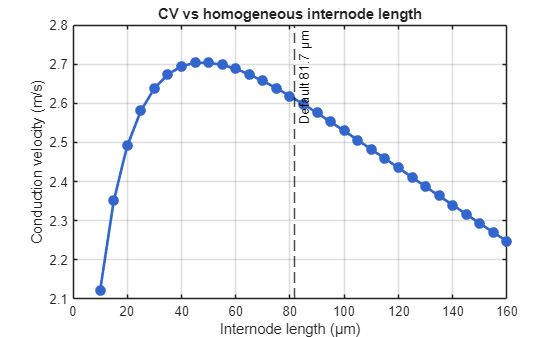


% Save results
save('results_CV.mat', 'L_values_um', 'CV');

% Plot
figure;
plot(L_values_um, CV, 'o-', 'LineWidth', 2, 'Color', [0.2 0.4 0.8], ...
     'MarkerFaceColor', [0.2 0.4 0.8]);
xlabel('Internode length (µm)');
ylabel('Conduction velocity (m/s)');
title('CV vs homogeneous internode length');
xline(81.7, '--k', 'Default 81.7 µm');
grid on;